# 5.7.  Лучевая и геометрическая оптика

#### Закон отражения Снелля

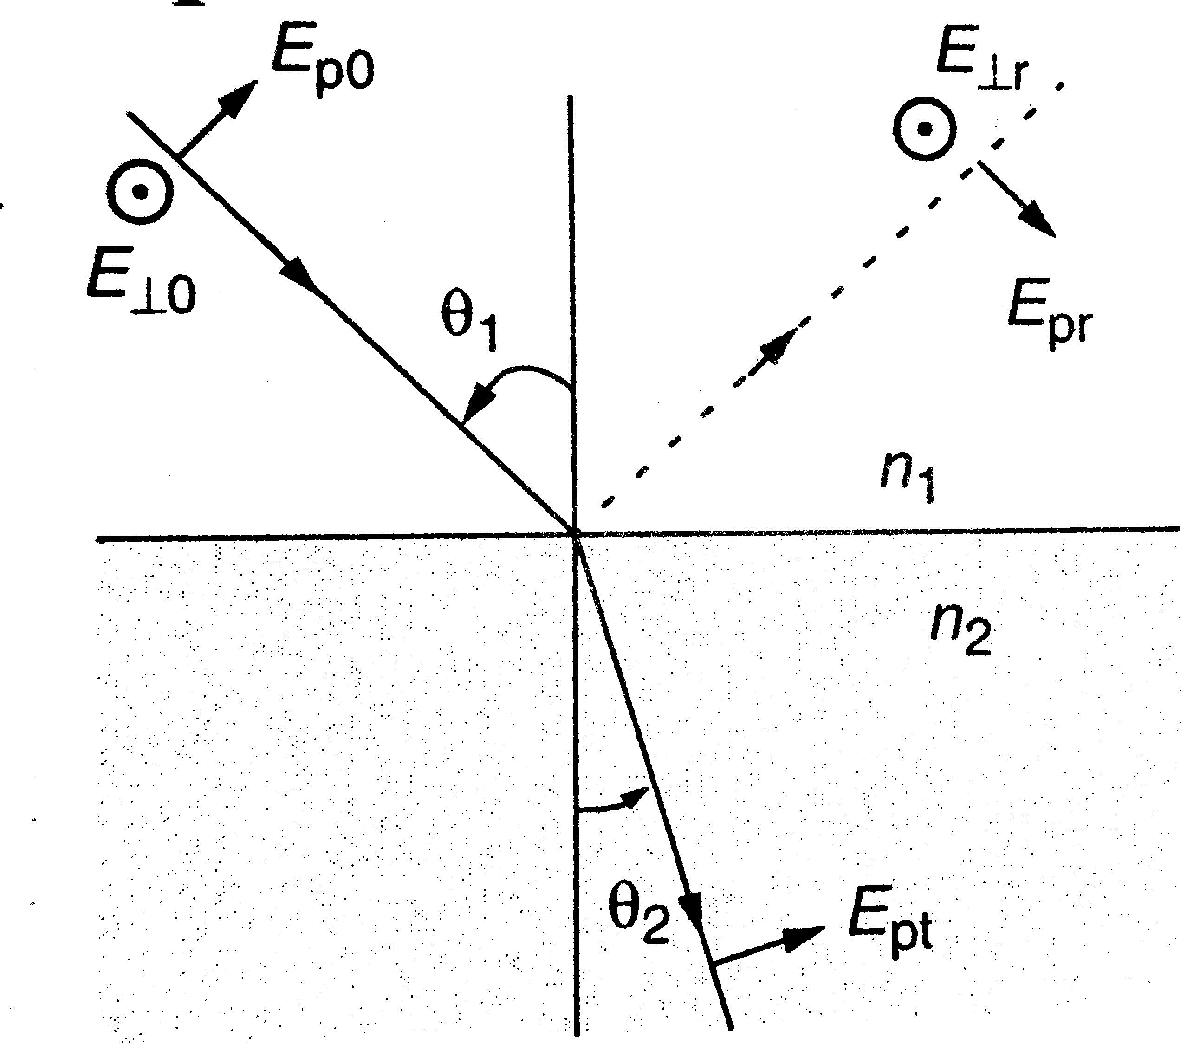

clear
syms n1 n2 theta1 theta2
n1*sin(theta1)==n2*sin(theta2)

$$ans = n_{1}\,\sin\left(\theta_{1}\right)=n_{2}\,\sin\left(\theta_{2}\right)$$

#### Критический угол полного отражения theta1_c

syms theta1_c n1 n2
sin(theta1_c)==n2/n1

$$ans = \sin\left(\theta_{1,c}\right)=\frac{n_{2}}{n_{1}}$$

#### Наименьшее отклонение в призме

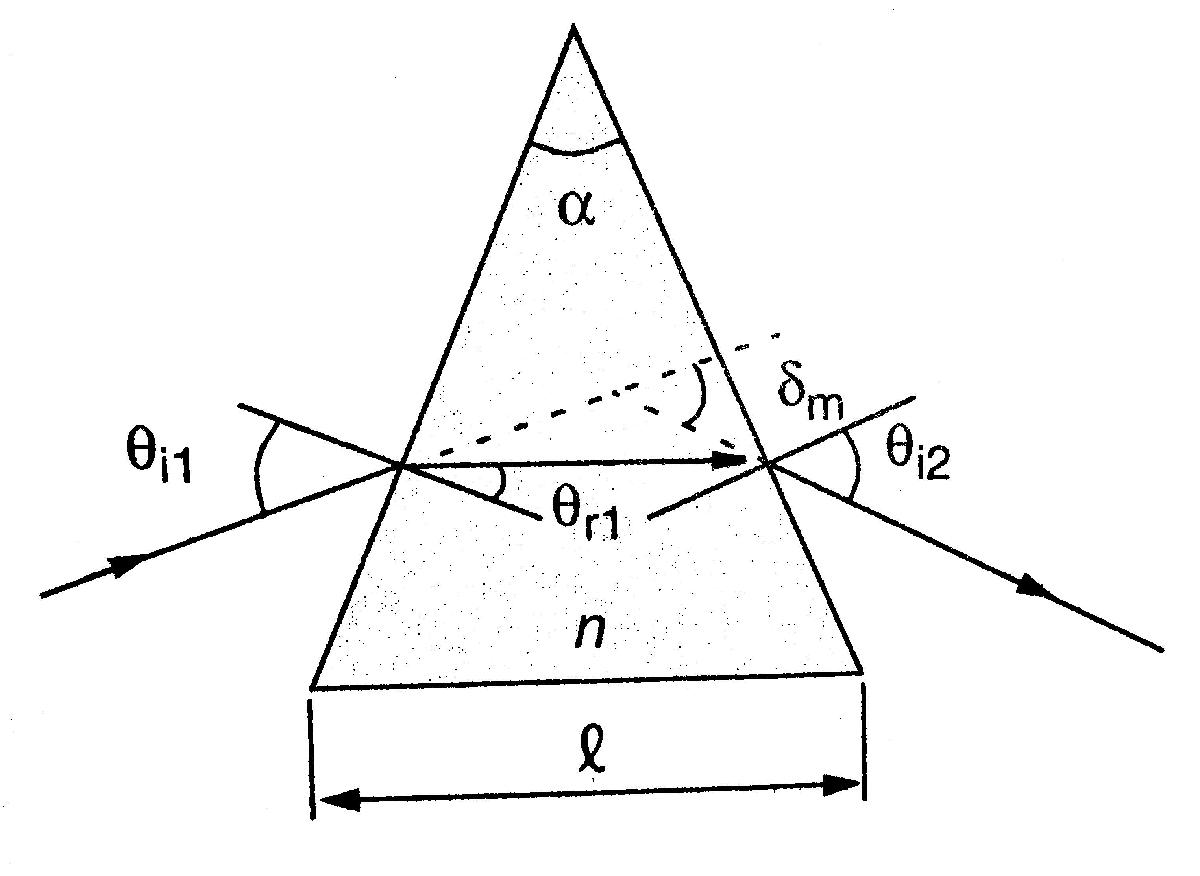

syms theta_i1 theta_i2 theta_i delta_m alpha n
theta_i1==theta_i2==theta_i

$$ans = \left(\theta_{\mathrm{i1}}=\theta_{\mathrm{i2}}\right)=\theta_{i}$$

delta_m==2*theta_i-alpha

$$ans = \delta_{m}=2\,\theta_{i}-\alpha$$

sin((alpha+delta_m)/2)==n*sin(alpha/2)

$$ans = \sin\left(\frac{\alpha }{2}+\frac{\delta_{m}}{2}\right)=n\,\sin\left(\frac{\alpha }{2}\right)$$

Дисперсия в призме

syms D delta(lambda) n(lambda) theta_i2 theta_r1
D==diff(delta,lambda)==diff(n,lambda)*sin(alpha)/(cos(theta_i2)*cos(theta_r1))

$$ans(lambda) = \left(\text{D}=\frac{\partial }{\partial \lambda }\delta \left(\lambda \right)\right)=\frac{\sin\left(\alpha \right)\,\frac{\partial }{\partial \lambda }n\left(\lambda \right)}{\cos\left(\theta_{\mathrm{i2}}\right)\,\cos\left(\theta_{\mathrm{r1}}\right)}$$

В частности, при наименьшем отклонении

D==diff(n,lambda)*2*sin(alpha/2)/cos(1/2*(delta_m+alpha))

$$ans(lambda) = \text{D}=\frac{2\,\sin\left(\frac{\alpha }{2}\right)\,\frac{\partial }{\partial \lambda }n\left(\lambda \right)}{\cos\left(\frac{\alpha }{2}+\frac{\delta_{m}}{2}\right)}$$

Разрешающая способность призмы

syms R lambda Delta(x) l n(lambda)
R==lambda/Delta(lambda)==-l*diff(n,lambda)

$$ans(lambda) = \left(R=\frac{\lambda }{\Delta \left(\lambda \right)}\right)=-l\,\frac{\partial }{\partial \lambda }n\left(\lambda \right)$$

% Delta(lambda) = наименьшая разница длин волн для двух
% разрешенных линий

#### Два примера

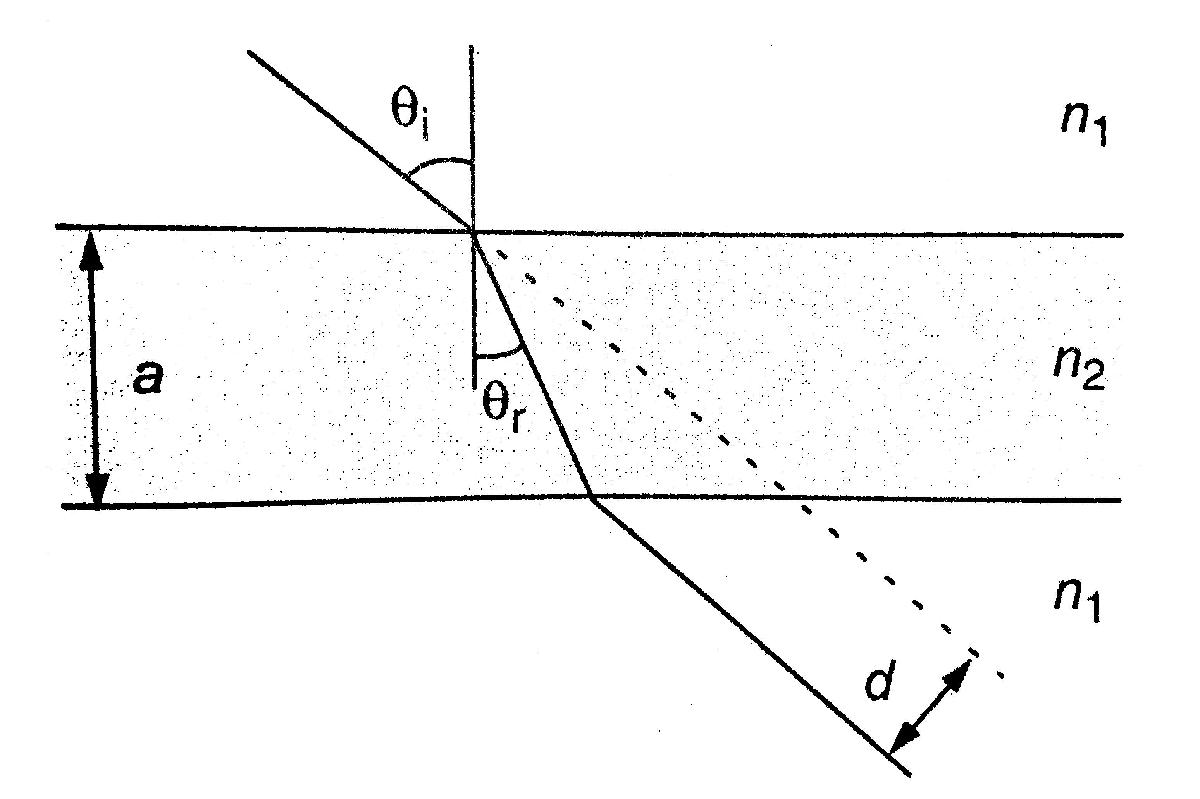

syms d theta_r a theta_i theta_r
d*cos(theta_r)==a*sin(theta_i-theta_r)

$$ans = d\,\cos\left(\theta_{r}\right)=a\,\sin\left(\theta_{i}-\theta_{r}\right)$$

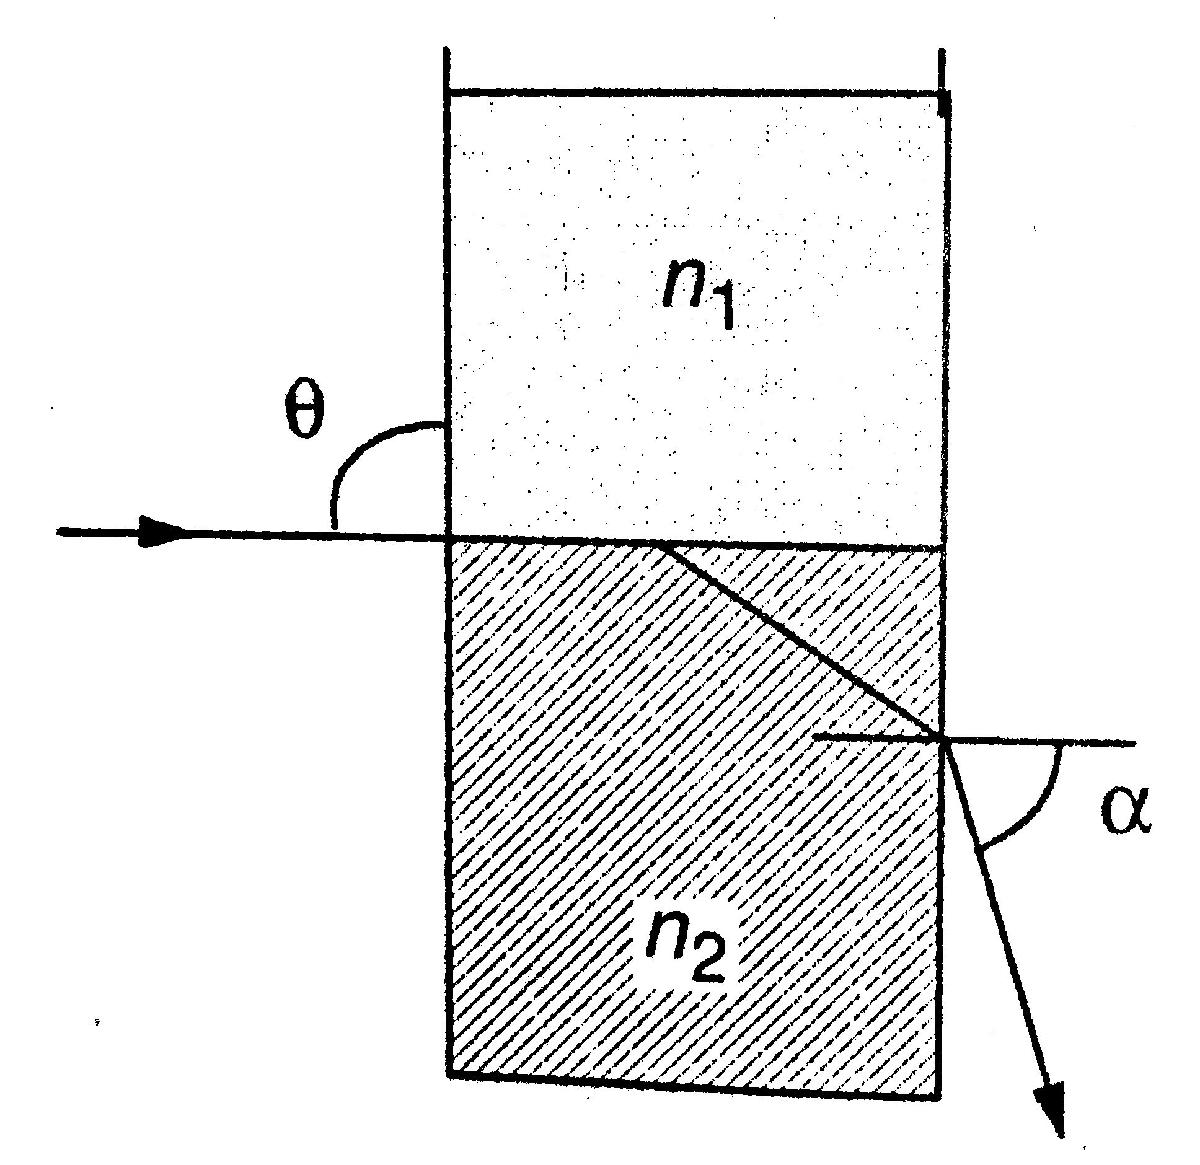

n1^2==n2^2-sin(alpha)^2

$$ans = {n_{1}}^{2}={n_{2}}^{2}-{\sin\left(\alpha \right)}^{2}$$

(Это способ измерить n1 или n2. theta несколько меньше чем 90 и n1<n2)

#### Формула зеркала

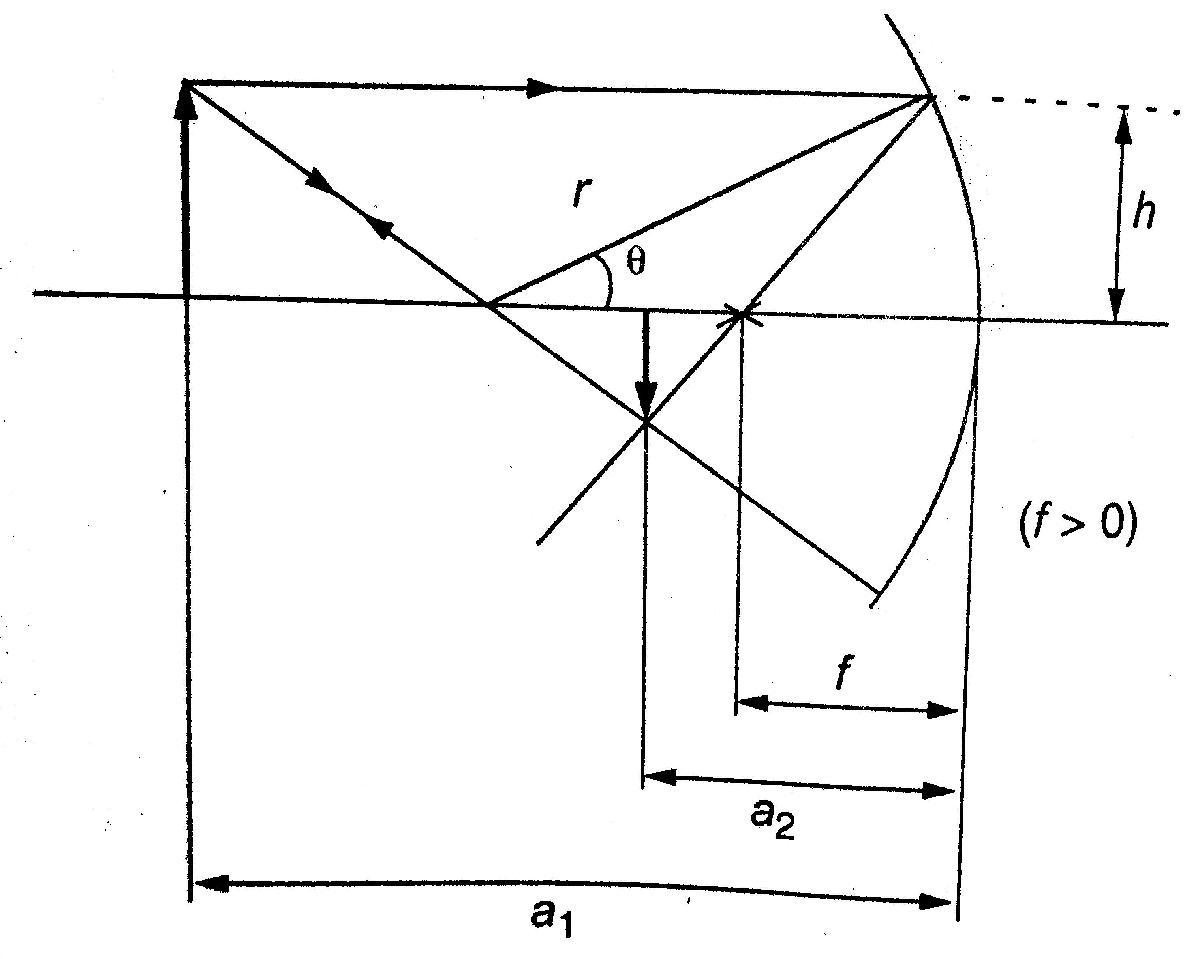

clear
syms f r theta
f==r*(1-1/(2*cos(theta)))

$$ans = f=-r\,\left(\frac{1}{2\,\cos\left(\theta \right)}-1\right)$$

Для малого theta

syms a1 a2 r f
1/a1+1/a2==2/r==1/f

$$ans = \left(\frac{1}{a_{1}}+\frac{1}{a_{2}}=\frac{2}{r}\right)=\frac{1}{f}$$

Линейное увеличение

syms M 
M==-a2/a1

$$ans = M=-\frac{a_{2}}{a_{1}}$$

Нецентральные лучи

syms a1 a2 r h theta
1/a1+1/a2==2/r+h^2/r*(1/r-1/a1)^2

$$ans = \frac{1}{a_{1}}+\frac{1}{a_{2}}=\frac{2}{r}+\frac{h^{2}\,{\left(\frac{1}{a_{1}}-\frac{1}{r}\right)}^{2}}{r}$$

h==r*sin(theta)

$$ans = h=r\,\sin\left(\theta \right)$$

% a1 и a2 положительны для действительного объекта
% и действительного изображения
% f и r положительны для вогунтого зеркала и отрицательны
% для выпуклого.

#### Преломление на сферической поверхности

syms n1 n2 a1 a2 r
n1/a1+n2/a2==(n2-n1)/r

$$ans = \frac{n_{1}}{a_{1}}+\frac{n_{2}}{a_{2}}=-\frac{n_{1}-n_{2}}{r}$$

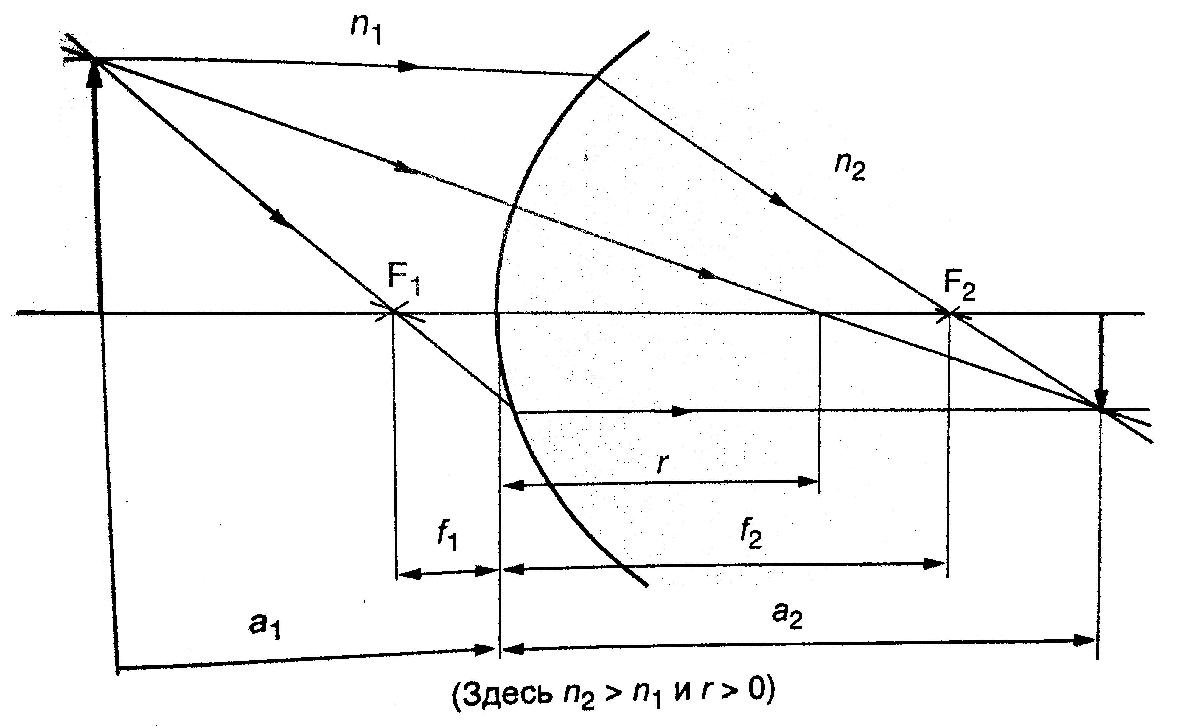

Фокусные расстояния

syms f1 f2 n1 n2 r
f1==n1*r/(n2-n1), f2==n2*r/(n2-n1)

$$ans = f_{1}=-\frac{n_{1}\,r}{n_{1}-n_{2}}$$

$$ans = f_{2}=-\frac{n_{2}\,r}{n_{1}-n_{2}}$$

Линейное увеличение

syms M n1 n2 a1 a2
M==-n1*a2/(n2*a1)

$$ans = M=-\frac{a_{2}\,n_{1}}{a_{1}\,n_{2}}$$

% a1 и a2 положительны для действительного объекта
% и действительного изображения

#### Фокусное расстояние тонкой линзы (формула линзового мастера)

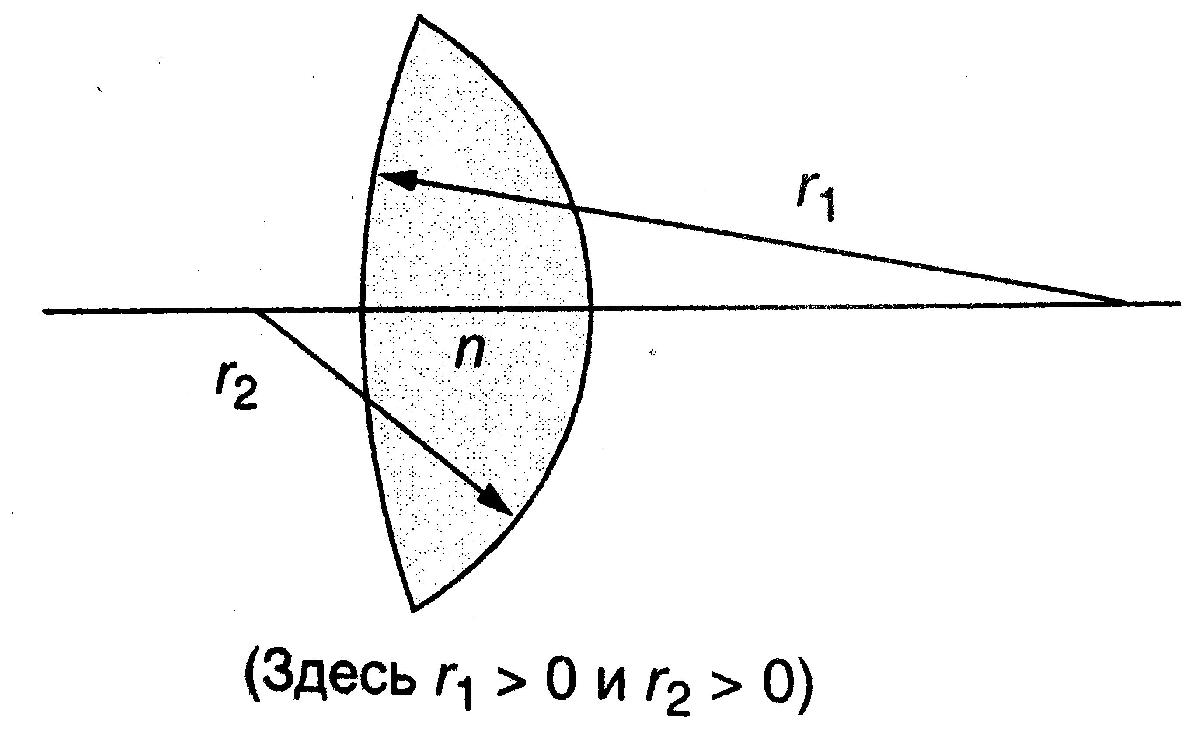

syms f n r1 r2
1/f==(n-1)*(1/r1+1/r2)

$$ans = \frac{1}{f}=\left(\frac{1}{r_{1}}+\frac{1}{r_{2}}\right)\,\left(n-1\right)$$

#### Тонкие линзы

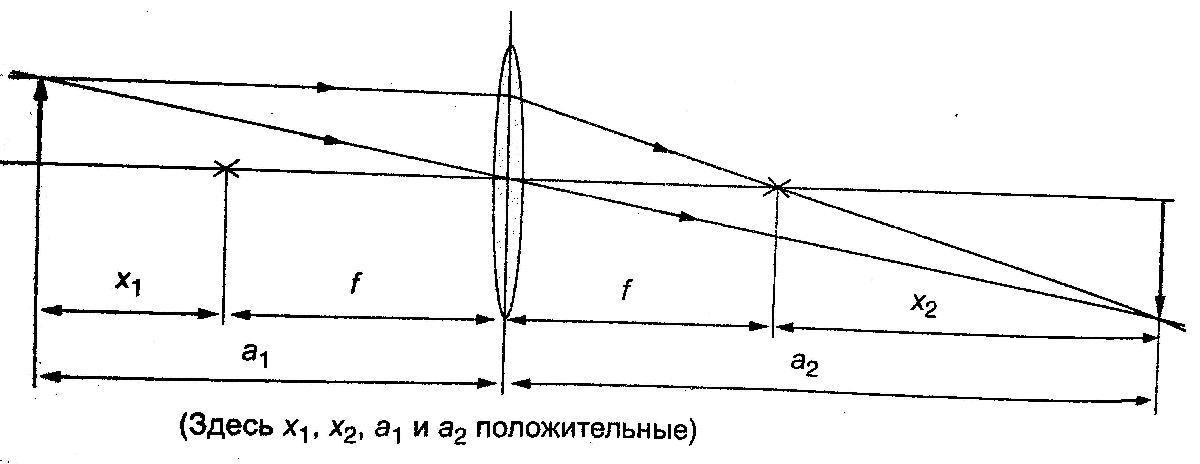

Формула Ньютона для линзы

syms x1 x2 f
x1*x2==f^2

$$ans = x_{1}\,x_{2}=f^{2}$$

% a1 и a2 положительны, если и объект и изображение действительны

Форумла Гаусса для линзы

syms a1 a2 f
1/a1+1/a2==1/f

$$ans = \frac{1}{a_{1}}+\frac{1}{a_{2}}=\frac{1}{f}$$

Линейное увеличение

syms M a1 a2
M==-a2/a1

$$ans = M=-\frac{a_{2}}{a_{1}}$$

#### Число диоптрий

syms D f
D==1/f

$$ans = \text{D}=\frac{1}{f}$$

% если f дано в метрах

#### Система из двух тонких линз, расстояния измеряются от линз

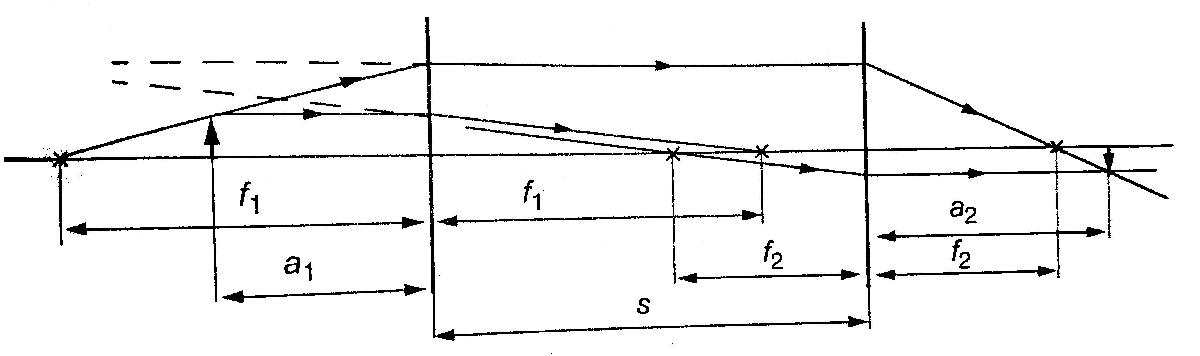

syms s a1 a2 f1 f2
s==a1*f1/(a1-f1)+a2*f2/(a2-f2)

$$ans = s=\frac{a_{1}\,f_{1}}{a_{1}-f_{1}}+\frac{a_{2}\,f_{2}}{a_{2}-f_{2}}$$

Линейное увеличение

syms M f1 f2 a1 a2
M==f1/f2*(a2-f2)/(a1-f1)

$$ans = M=\frac{f_{1}\,\left(a_{2}-f_{2}\right)}{f_{2}\,\left(a_{1}-f_{1}\right)}$$

#### Фокусное расстояние и положение главных плоскостей в системе толстой линзы

syms f n r1 r2 d k1 k2
1/f==(n-1)*(1/r1+1/r2-(n-1)/n*d/(r1*r2))

$$ans = \frac{1}{f}=\left(n-1\right)\,\left(\frac{1}{r_{1}}+\frac{1}{r_{2}}-\frac{d\,\left(n-1\right)}{n\,r_{1}\,r_{2}}\right)$$

k1==(n-1)/n*d/r2*f

$$ans = k_{1}=\frac{d\,f\,\left(n-1\right)}{n\,r_{2}}$$

k2==(n-1)/n*d/r1*f

$$ans = k_{2}=\frac{d\,f\,\left(n-1\right)}{n\,r_{1}}$$

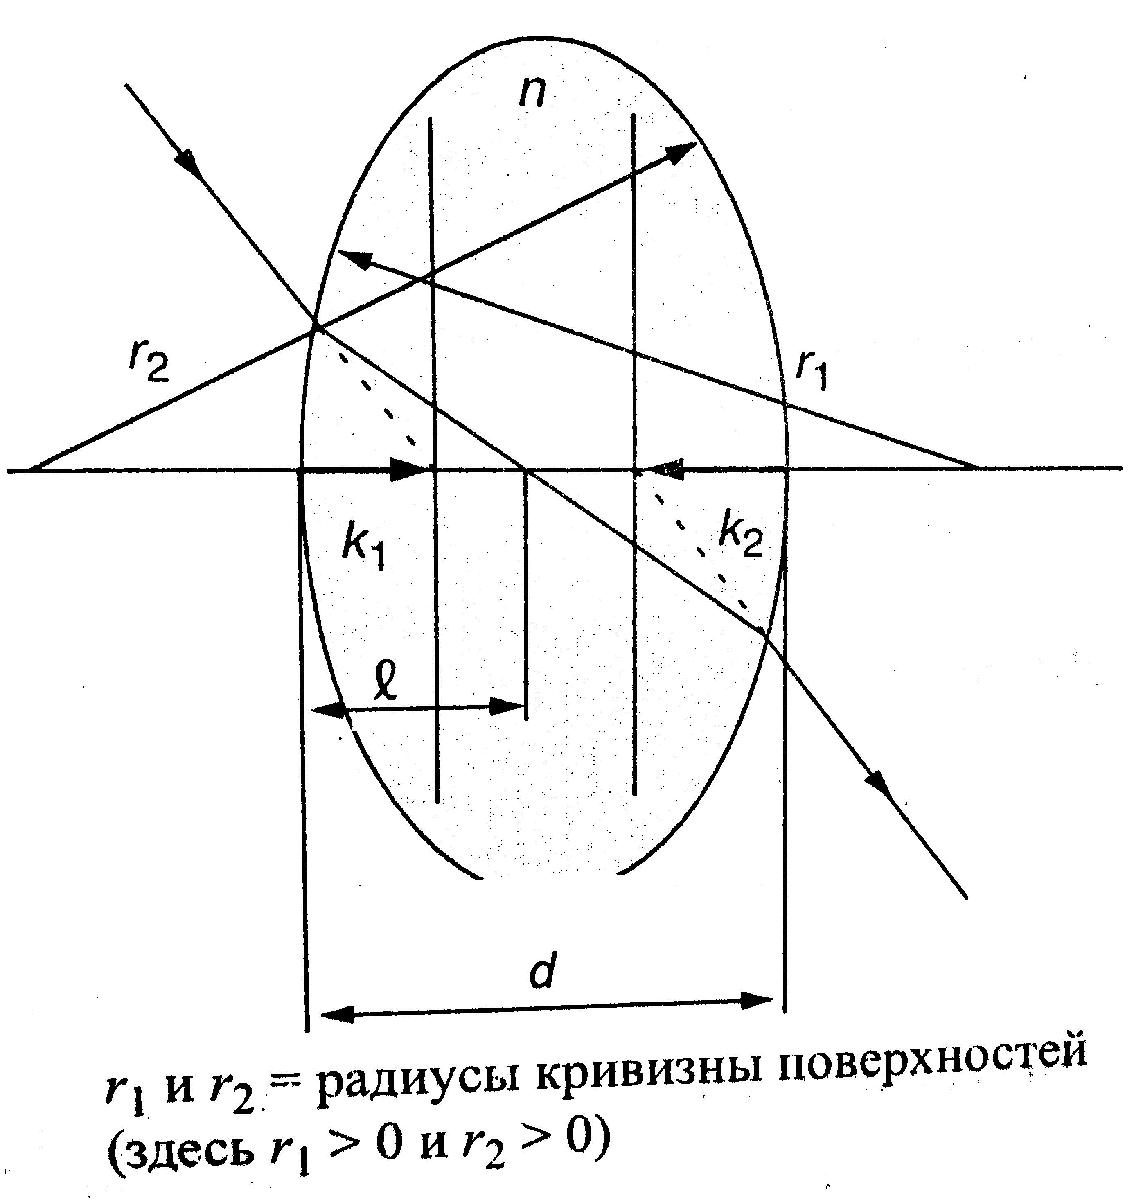

% (Показатель преломления одинаков на обеих сторонах линзы)

Положение оптического центра

syms l r1 r2 d 
l==r1*d/(r1+r2)

$$ans = l=\frac{d\,r_{1}}{r_{1}+r_{2}}$$